# ELTD2 - 2024/2 | Aula 03

Este é um *live script* do MATLAB (mais infos [aqui](https://www.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html)). A extensão é .mlx. Pode ser aberto no MATLAB Online ou local.

## **Exemplo de aplicação de image enhancement**

O trabalho científico abaixo (paper) aplica operações ponto-a-ponto e baseadas no histograma para melhoramento de imagens (image enhancement).

Rahman T, Khandakar A, Qiblawey Y, Tahir A, Kiranyaz S, Abul Kashem SB, Islam MT, Al Maadeed S, Zughaier SM, Khan MS, Chowdhury MEH. **Exploring the effect of image enhancement techniques on COVID-19 detection using chest X-ray images**. *Comput Biol Med.* 2021 May;132:104319. doi: 10.1016/j.compbiomed.2021.104319. Epub 2021 Mar 11. PMID: 33799220; PMCID: PMC7946571. *Disponível em* [https://www.sciencedirect.com/science/article/pii/S001048252100113X](https://www.sciencedirect.com/science/article/pii/S001048252100113X)

Os próximos tópicos deste *live script* apresentam as operações utilizadas no paper.

### 1. Negative (image invert/complement)

For an 8-bit grayscale image, the original pixel is subtracted from the highest intensity value ($255$), the difference is considered as pixel values for the new image. For X-ray images, the dark spots turn lighter and light spots become darker. The mathematical expression is simply as follows [2]:


$$y = 255 - x$$


where: $x$ is the input image and $y$ is the output image

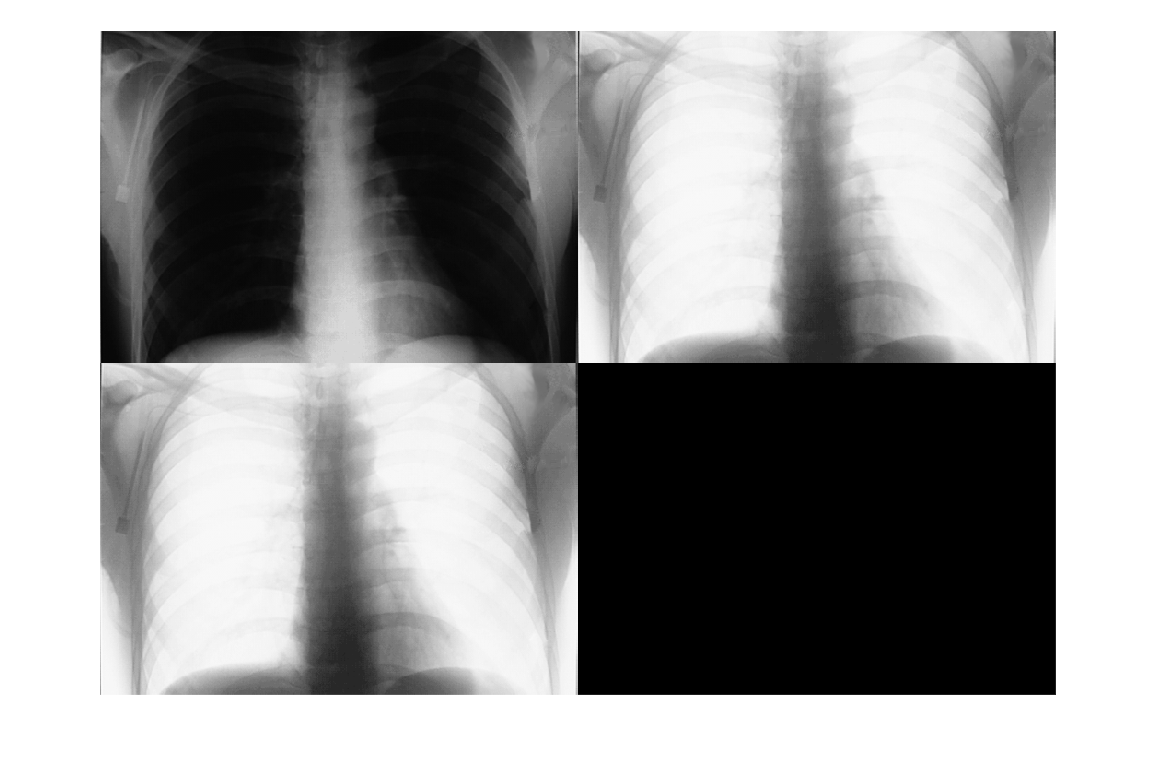

% Negative (image invert/complement)
clc, clear

img = imread('phpEMp3Xr.png');

% Negative 'na unha'
img_neg_1 = 255 - img;

% Negative unsando função imcomplement
img_neg_2 = imcomplement(img);

% Show
figure
montage({img, img_neg_1, img_neg_2})

### 2. Gamma correction

Gamma correction is a method initially devised to tackle the discrepancies between sensors and display units in analog television systems because light intensity, whether captured by the camera or reproduced on the screen, doesn’t correspond linearly with voltage levels. In addition to pre-compensating for the non-linearity of the display, gamma correction has the added benefit of encoding the luminance information into a perceptually uniform space, thus compensating for the nonlinear characteristics of the human visual system. Moreover, the gamma-corrected signal also becomes less sensitive to noise [1].

Outside of TV systems, gamma correction can be applied to individual images as a type of nonlinear intensity transformation function (also known as *power-law function*), described mathematically as [1]:  


$$s = c \cdot r^{\gamma}$$


where: $r$ is the original pixel value, $s$ is the resulting pixel value, $c$ is a scaling constant, and $\gamma$ **is a positive value**.

The Figure bellow (source: [MathWorks](https://www.mathworks.com/help/images/ref/imadjust.html)) shows the shape of the transformation curves when $\gamma$ is less than 1, equal to 1, and greater than 1.

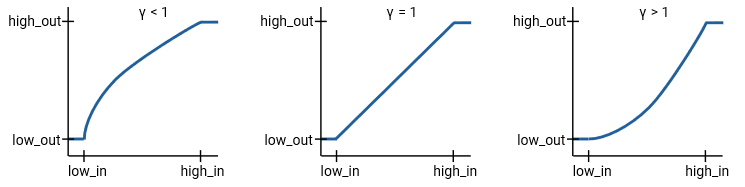

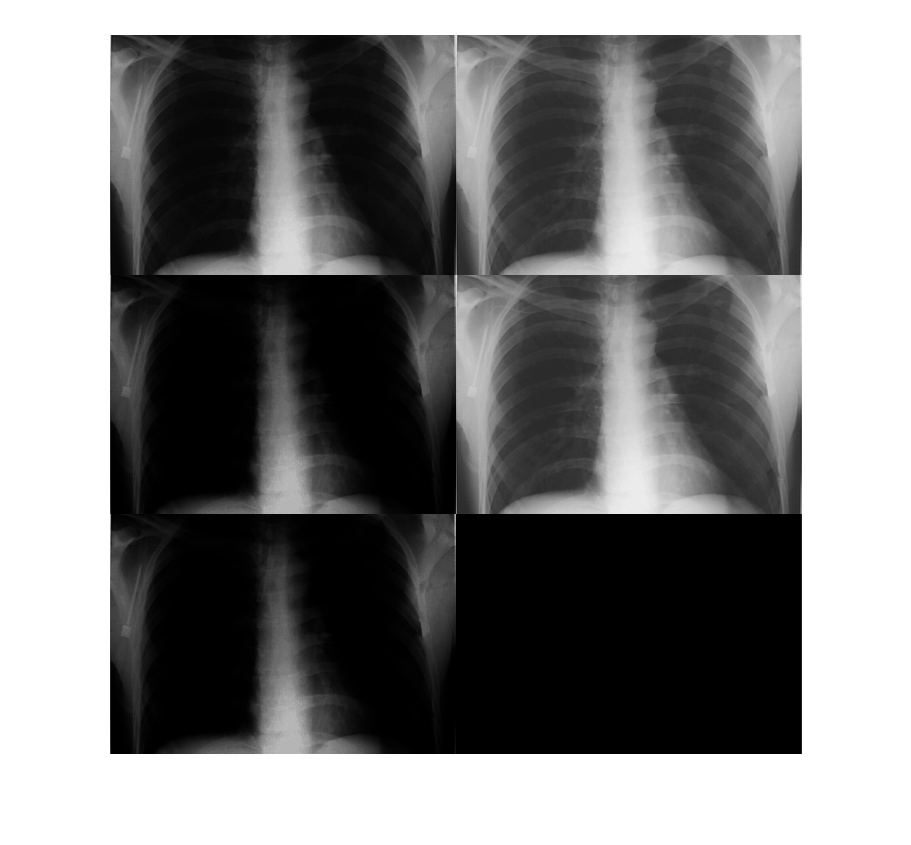

% Gamma correction
clc, clear

img = imread('phpEMp3Xr.png');
img_d = im2double(img);

% Gamma 'na unha'
img_gamma_1 = img_d.^0.5; % gamma < 1 -> imagem de saída mais clara
img_gamma_2 = img_d.^2;   % gamma > 1 -> imagem de saída mais escura

% Gamma usando função imadjust
img_gamma_3 = imadjust(img_d, [], [], 0.5); % gamma < 1 -> imagem de saída mais clara
img_gamma_4 = imadjust(img_d, [], [], 2);   % gamma > 1 -> imagem de saída mais escura

% Show
figure
montage({img, img_gamma_1, img_gamma_2, img_gamma_3, img_gamma_4})

### 3. Balance contrast enhancement technique (BCET)

BCET represents an approach for improving balance contrast by stretching or compressing the contrast of the image without altering the histogram pattern of the image data. The solution is based on the parabolic function acquired from the image data. The general parabolic functional form using $y$ coordinate and $x$ coordinate in an $XY$ plane is defined as [2]


$$y = a(x-b)^2+c$$


The three coefficients $a$, $b$ and $c$ are determined from the following equations,


$$b = \frac{ h^2(E-L) -  e(H-L) + l^2(H-E)} {2(h(E-L) - e(H-L) + l(H-E)) }$$



$$a = \frac{H-L}{(h-l)(h+l-2b)}$$



$$c = L - a(l-b)^2$$


where

$l$: minimum value of the input image

$h$: maximum value of the input image

$e$: mean value of the input image

$L$: minimum value of the output image

$H$: maximum value of the input image

$E
$: mean value of the output image

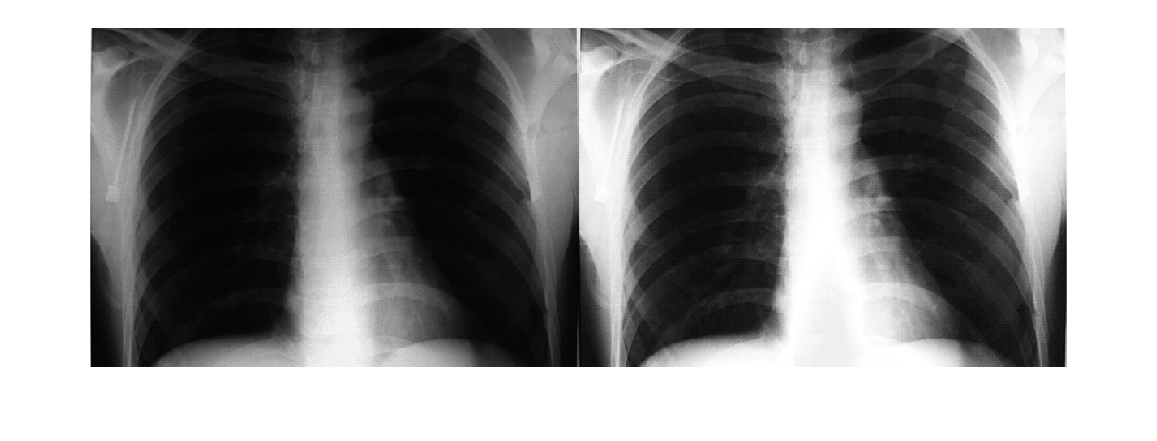

% Balance contrast enhancement technique (BCET)
clc, clear

img = imread('phpEMp3Xr.png');
img_d = im2double(img);

% Input
l = min(img_d(:));
h = max(img_d(:));
e = mean(img_d(:));

% Output desired parameters
L = 0.1; % experimentations...
H = 0.9; % experimentations...
E = e;

% Computing coefficient b
b = ( (h*h)*(E-L) - e*(H-L) + (l*l)*(H-E) ) / ( 2*( h*(E-L) - e*(H-L) + l*(H-E) ) );

% Computing coefficient a
a = (H-L) / ( (h-l)*(h+l-2*b) );

% Computing coefficient c
c = L - a*(l-b)^2;

% BCET
img_d_bcet = a .* (( img_d - b ).^2) + c;

figure
imshowpair(img_d, img_d_bcet, "montage")

### 4. Histogram equalization

Histogram equalization is a technique that rearranges the distribution of pixel values in a grayscale image to produce a uniform histogram, in which the percentage of pixels of every gray level is the same (ideally the same, because since we are dealing with digital images, this is usually not possible and we have to settle for a resulting histogram that is “as close to a uniform distribution as it can get”). The basic histogram equalization technique (available in MATLAB as histeq function) can be used as a contrast enhancement algorithm when the original image’s gray levels are grouped in a narrow range of gray levels [1].

The following steps descripes the procedure to perform an histogram equalization:

- Obtain the histogram of the original image.

- Normalize this histogram: divide each bin of the histogram by the number of pexels of the image.

- Obtain the cumulative distribution function (CDF): make the cumulative sum of the histogram of step 2.

- Transform the CDF into rounded gray levels: multiply by 255 and convert to an 8-bit unsigned integer.

- Apply the vector from step 4 as a transformation function on the original image.

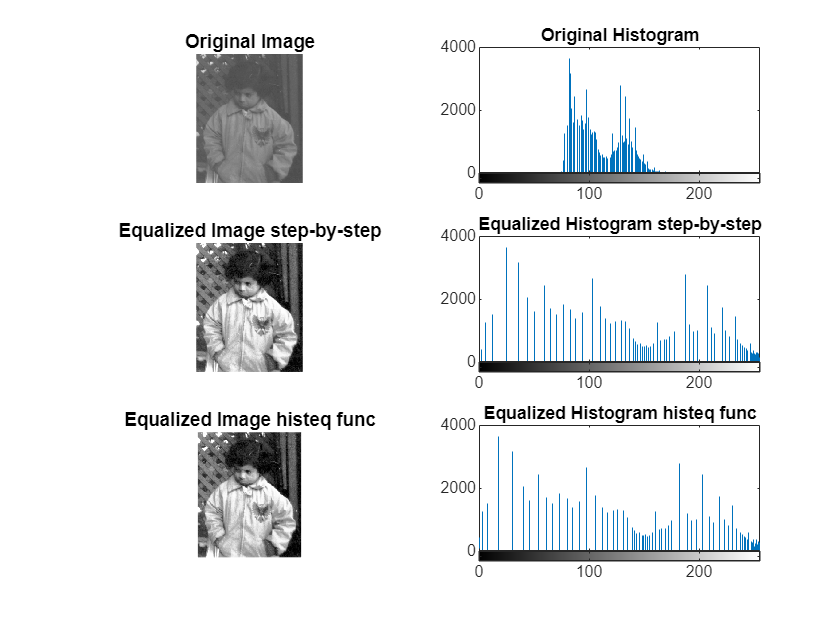

% Histogram equalization
clc, clear

img = imread('pout.tif');
[n_rows, n_cols] = size(img);

% Histogram equalization step-by-step
% 1. Obtain the histogram of the original image
[counts, binLocations] = imhist(img);
% 2. Normalize this histogram
hist_norm = counts/(n_rows*n_cols);
% 3. Obtain the cumulative distribution function (CDF)
cdf = cumsum(hist_norm);
% 4. Transform the CDF into rounded gray levels
transf_function = uint8(cdf*255);
% 5. Apply the vector from step 4 as a transformation function on the original image
img_hist_equaliz = intlut(img,transf_function);

% Histogram equalization using histeq function
img_histeq = histeq(img,256); 

% Show
figure
subplot(3,2,1), imshow(img), title('Original Image')
subplot(3,2,2), imhist(img), ylim('auto'), title('Original Histogram')
subplot(3,2,3), imshow(img_hist_equaliz), title('Equalized Image step-by-step') 
subplot(3,2,4), imhist(img_hist_equaliz), ylim('auto'), title('Equalized Histogram step-by-step')
subplot(3,2,5), imshow(img_histeq), ylim('auto'), title('Equalized Image histeq func')
subplot(3,2,6), imhist(img_histeq), ylim('auto'), title('Equalized Histogram histeq func')

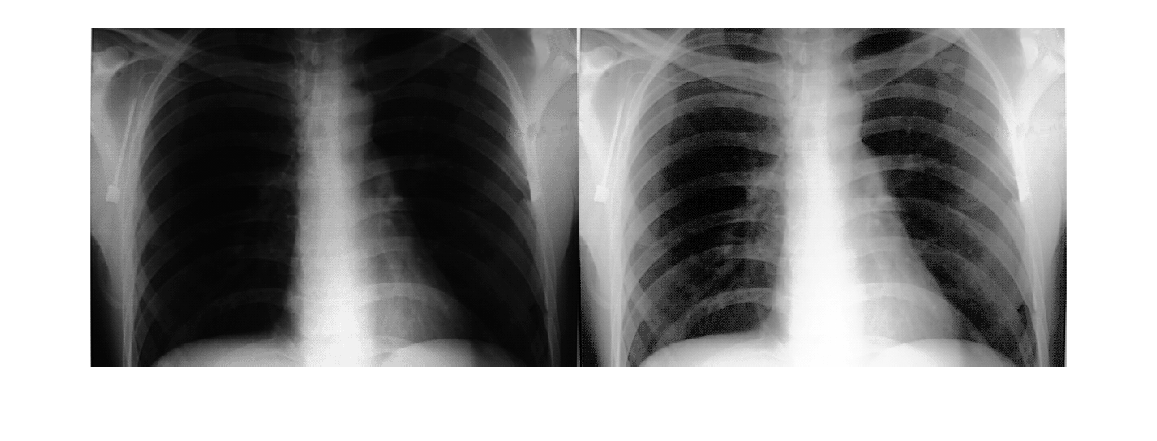


% Histogram equalization using histeq function
img_xray = imread('phpEMp3Xr.png');
img_xray_histeq = histeq(img_xray,256); 

% Show
figure
imshowpair(img_xray, img_xray_histeq, "montage")

### 5. Contrast-limited adaptive histogram equalization (CLAHE)

The Contrast-limited adaptive histogram Equalization (CLAHE) algorithm is an improved version of the regular histogram equalization. It operates on small regions in the image, called *tiles*, rather than the entire image (thus, CLAHE is a *local histogram equalization* technique). Basically, it calculates the contrast transform function for each tile individually, and neighboring tiles are combined using bilinear interpolation to eliminate artificially induced boundaries [1].

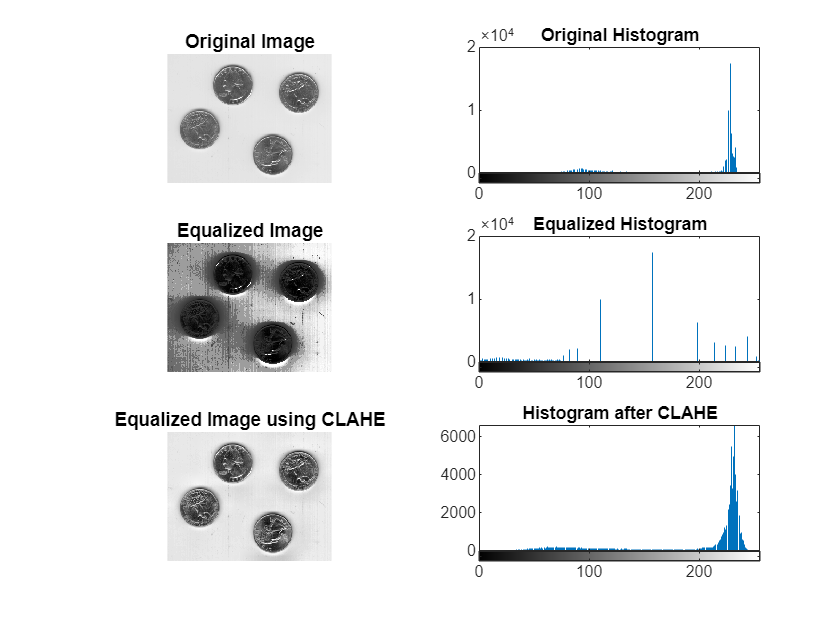

% Histogram equalization vs. CLAHE
clc, clear

img = imread('eight.tif');

img_eq = histeq(img,256);        % histogram equalization (also called 'global')
img_clahe_eq = adapthisteq(img); % CLAHE (also called 'local')

% Show
figure
subplot(3,2,1), imshow(img), title('Original Image')
subplot(3,2,2), imhist(img), ylim('auto'), title('Original Histogram')
subplot(3,2,3), imshow(img_eq), title('Equalized Image') 
subplot(3,2,4), imhist(img_eq), ylim('auto'), title('Equalized Histogram')
subplot(3,2,5), imshow(img_clahe_eq), title('Equalized Image using CLAHE') 
subplot(3,2,6), imhist(img_clahe_eq), ylim('auto'), title('Histogram after CLAHE')

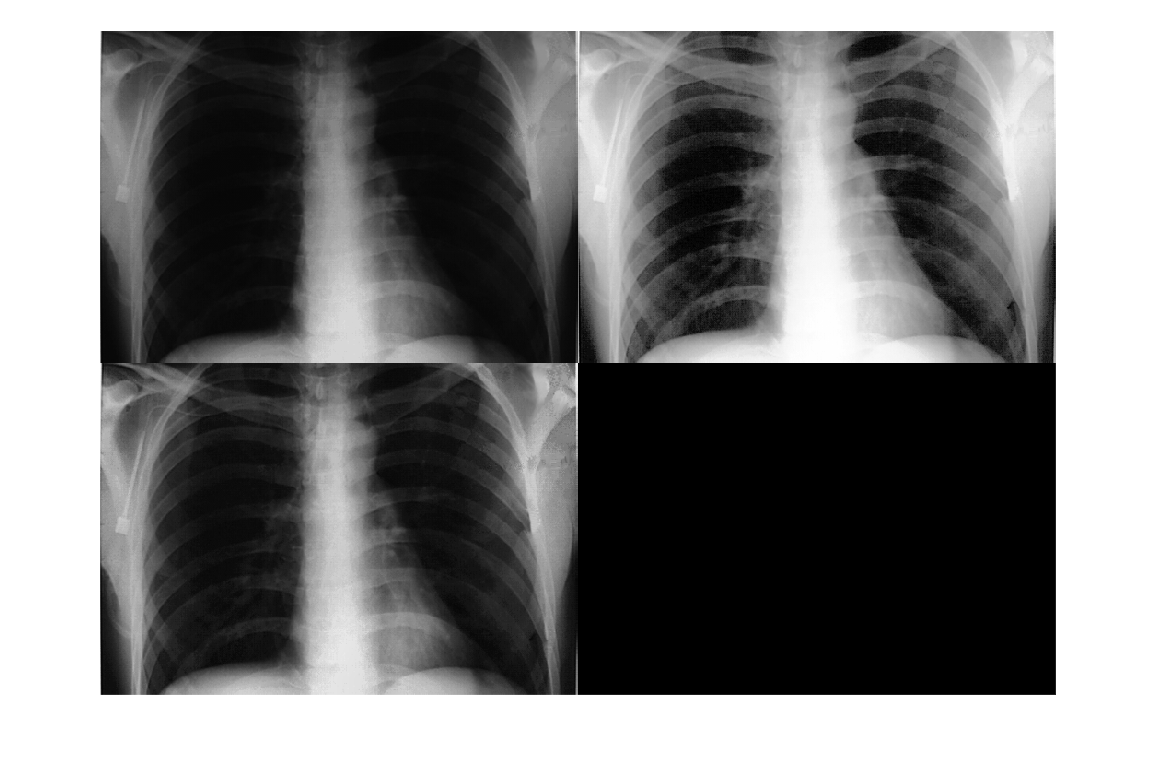

% Histogram equalization vs. CLAHE
img_xray = imread('phpEMp3Xr.png');
img_xray_eq = histeq(img_xray,256); 
img_xray_clahe_eq = adapthisteq(img_xray);

% Show
figure
montage({img_xray, img_xray_eq, img_xray_clahe_eq})

### 6. Complementary examples

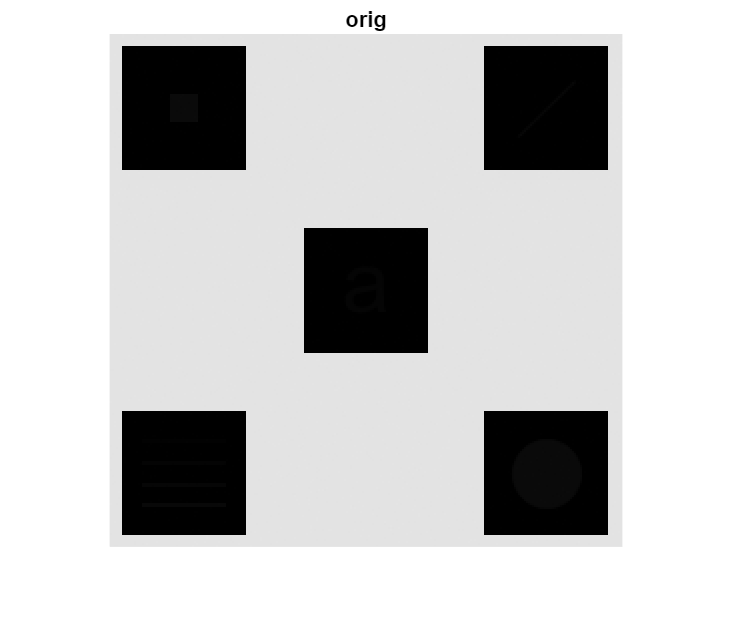

% Fig0326.tif: Rafael C. Gonzalez, Richard E. Woods and Steven L. Eddins.
% Digital Image Processing Using MATLAB. 3rd ed.
% Pearson Prentice Hall, 2020. Capítulo 3
clc, clear

i = imread('Fig0326.tif');
figure, imshow(i), title('orig')

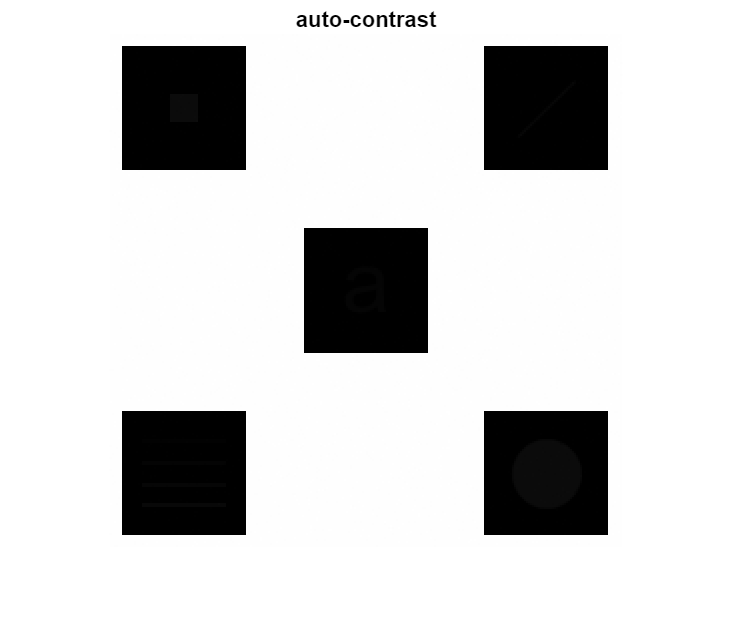


i_ac = mat2gray(i);
figure, imshow(i_ac), title('auto-contrast')

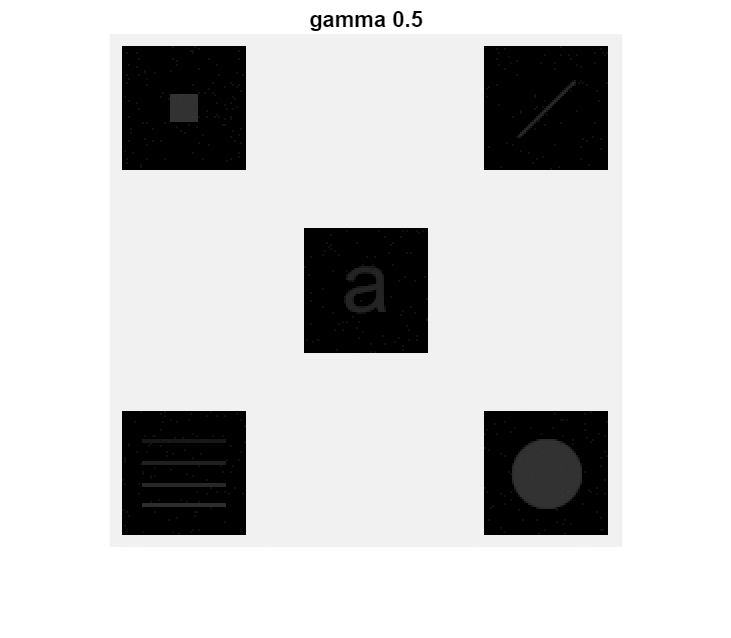


i_gamma = imadjust(i, [], [], 0.5);
figure, imshow(i_gamma), title('gamma 0.5')

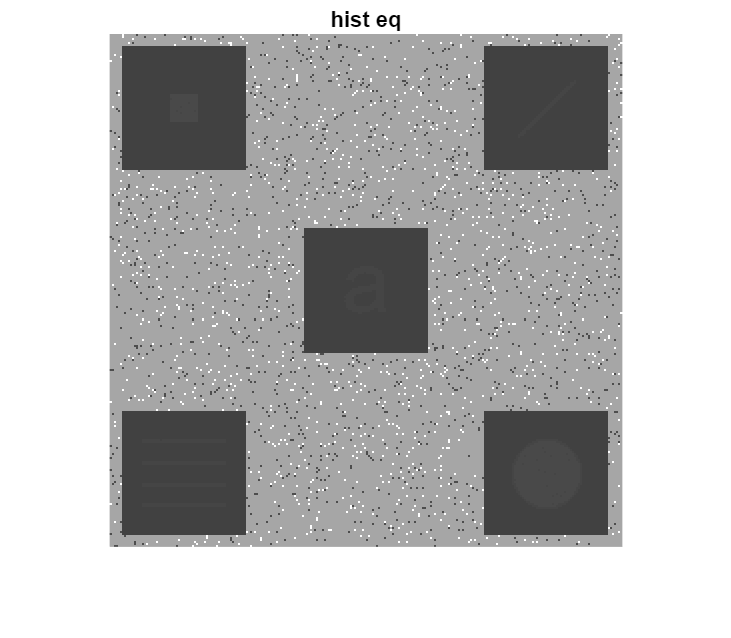


i_heq = histeq(i);
figure, imshow(i_heq), title('hist eq')

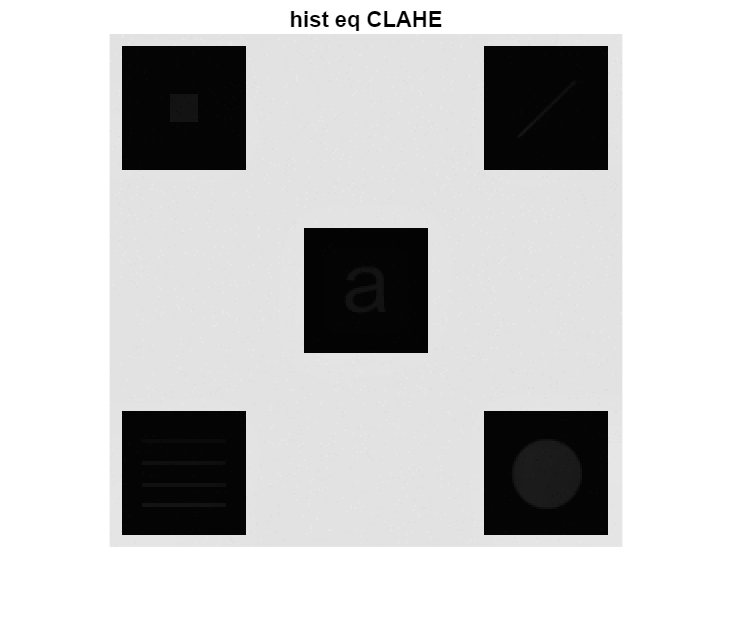


i_heql = adapthisteq(i);
figure, imshow(i_heql), title('hist eq CLAHE')

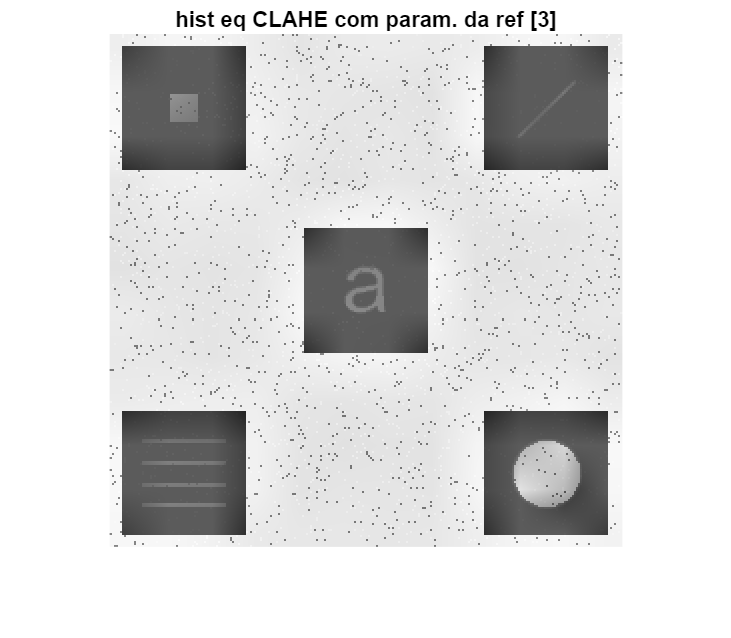

i_heql_p = adapthisteq(i,'ClipLimit',0.4,'Distribution','exponential','NumTiles',[12 12]);
figure, imshow(i_heql_p), title('hist eq CLAHE com param. da ref [3]')

### Referências

[1] Oge Marques and Gustavo B. Borba. *Image Processing Recipes in MATLAB*. CRC Press, 2024. Code available at GitHub: [https://github.com/ip-recipes-matlab-book](https://github.com/ip-recipes-matlab-book) **Livro completo em PDF:** [https://www.dropbox.com/scl/fo/i1nqbgxwir1y7xckrxmni/ADWO_UGeagLsnU3P-hHPXdk?rlkey=pisioihattpa1hn6h40mpbpy4&st=ubi18tox&dl=0](https://www.dropbox.com/scl/fo/i1nqbgxwir1y7xckrxmni/ADWO_UGeagLsnU3P-hHPXdk?rlkey=pisioihattpa1hn6h40mpbpy4&st=ubi18tox&dl=0) **Não compartilhar, não distribuir.** **Esta versão foi cedida pelos autores para utilização na disciplina.**

[2] Rahman T, Khandakar A, Qiblawey Y, Tahir A, Kiranyaz S, Abul Kashem SB, Islam MT, Al Maadeed S, Zughaier SM, Khan MS, Chowdhury MEH. **Exploring the effect of image enhancement techniques on COVID-19 detection using chest X-ray images**. *Comput Biol Med.* 2021 May;132:104319. doi: 10.1016/j.compbiomed.2021.104319. Epub 2021 Mar 11. PMID: 33799220; PMCID: PMC7946571. Disponível em [https://www.sciencedirect.com/science/article/pii/S001048252100113X](https://www.sciencedirect.com/science/article/pii/S001048252100113X)

[3] Rafael C. Gonzalez, Richard E. Woods and Steven L. Eddins.* Digital Image Processing Using MATLAB.* 3rd ed. Pearson Prentice Hall, 2020. Site do livro:  [https://www.imageprocessingplace.com](https://www.imageprocessingplace.com/)